clear all
clc
n = 12;
Sb = 100e6;
datos_linea = [4 5 0.01 1j*0.068 1j*0.0348; 4 6 0.017 1j*0.092 1j*0.0549; 5 7 0.011308 1j*0.02832 1j*0.0317638; 6 9 0.039 1j*0.1738 1j*0.0358; 6 12 0.023 1j*0.18 1j*0.0236; 7 8 0.008477 1j*0.057522 1j*0.158821; 8 9 0.0119 1j*0.1008 1j*0.0209; 10 11 0.031 1j*0.123 1j*0.0123];
X_tridevanado = [0.06 0.07 0.025; 350e6 200e6 150e6];
Xpst = Impedancias_tridevanado(X_tridevanado, Sb)

Xpst =    -0.0006    0.0177    0.0173


%Barra1 Barra 2 X12 tapmax pasos_tap delta1 
datos_trafos = [1 13 1j*Xpst(1) 0.1 0.02 0; 4 13 1j*Xpst(2) 0.1 0.02 0; 10 13 1j*Xpst(3) 0.1 0.02 deg2rad(330); 2 7 1j*0.011 0 0 deg2rad(30); 3 9 1j*0.073 0 0 deg2rad(-30); 11 12 1j*0.22 0.1 0.02 deg2rad(-30)];
disp('Info del sistema')

Info del sistema


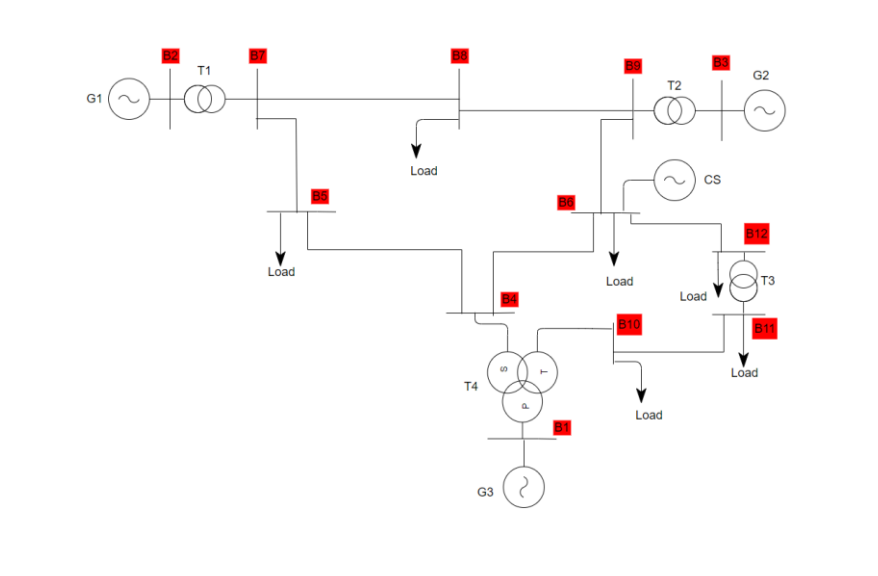

SP = imread('Sistema_potencia_ejp.png');
imshow(SP)

disp('Líneas : ')

Líneas : 


for i = 1:length(datos_linea(:,1))
    l = ['Linea ', num2str(i), ': ', num2str(datos_linea(i,1)), ' - ', num2str(datos_linea(i,2))];
    disp(l)
end

Linea 1: 4 - 5


Linea 2: 4 - 6


Linea 3: 5 - 7


Linea 4: 6 - 9


Linea 5: 6 - 12


Linea 6: 7 - 8


Linea 7: 8 - 9


Linea 8: 10 - 11


disp('Trafos: ')

Trafos: 


for i = 3:length(datos_trafos(:,1))
    if i == 3
        l = ['Trafo ', num2str(1), ' : ', num2str(datos_trafos(1,1)), ' - ', num2str(datos_trafos(2,1)), ' - ', num2str(datos_trafos(3,1)), ' -- ', 'LTC : ', num2str(datos_trafos(1,4)), '/', num2str(datos_trafos(1,5))];
    elseif datos_trafos(i,4)  ~= 0
        l = ['Trafo ', num2str(i-2), ' : ', num2str(datos_trafos(i,1)), ' - ', num2str(datos_trafos(i,2)),' -- ', 'LTC : ', num2str(datos_trafos(i,4)), '/', num2str(datos_trafos(i,5))];
    else 
        l = ['Trafo ', num2str(i-2), ' : ', num2str(datos_trafos(i,1)), ' - ', num2str(datos_trafos(i,2))];
    end
    disp(l)
end

Trafo 1 : 1 - 4 - 10 -- LTC : 0.1/0.02


Trafo 2 : 2 - 7


Trafo 3 : 3 - 9


Trafo 4 : 11 - 12 -- LTC : 0.1/0.02


LTC = datos_trafos(datos_trafos(:,4) ~= 0, :);
Q1 = input('¿Desea desconectar una línea? \n Sí: 1 - No: 2 \n');
if Q1 == 1
    line = input('¿Qué línea desea desconectar?');
else
    line = false;
end
pasos = [];
for i = 3:length(LTC(:,1))
    if i == 3
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(1,1)), ' - ', num2str(LTC(2,1)), ' - ', num2str(LTC(3,1)), '? \n'];
    else
        ltc = ['¿Cuántos pasos desea tomar en el tap del trafo conectado a las barras ',num2str(LTC(i,1)), ' - ', num2str(LTC(i,2)), '? \n'];
    end
    Q2 = input(ltc);
    pasos(i) = Q2;
end
Y_barra = Matriz_Ybarra2(datos_linea,n,line,datos_trafos,pasos)

Y_barra =    0.2000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1000 + 0.0000i
   0.0000 + 0.0000i   0.1000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1000 - 0.0009i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1000 + 0.0009i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   4.1590 -24.8156i  -2.1169 +14.3946i  -1.9422 +10.5107i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1000 + 0.0000

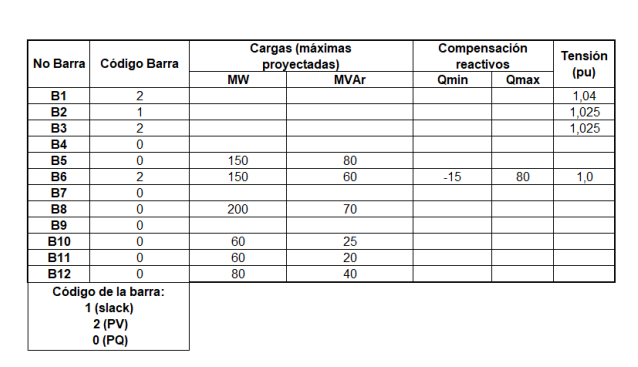

% 0 -> Slack; 1 -> PV; 2 -> PQ
%[Barra Tipo Pgen Qgen Pd Qd Qmin Qmax V delta]
%SLACK SIEMPRE VA EN LA PRIMERA FILA
datos_potencia = [2 0 false false false false false false 1.025 0;13 2 0 0 0 0 0 0 0 0;1 1 false false false false false false 1.04 0; 3 1 false false false false false false 1.025 0; 4 2 false false false false false false 1 0; 5 2 false false 150e6 80e6 false false 1 0; 6 1 false false 150e6 60e6 -15e6 80e6 1 0; 7 2 false false false false false false 1 0; 8 2 false false 200e6 70e6 false false 1 0; 9 2 false false false false false false 1 0; 10 2 false false 60e6 25e6 false false 1 0; 11 2 false false 60e6 20e6 false false 1 0; 12 2 false false 80e6 40e6 false false 1 0];
[V, delta, count] = Newton_Raphson(Y_barra, datos_potencia, 1.02, Sb, "normal")

deltas_pot =    -0.0020
   -0.0042
   -0.1066
    0.0529
   -1.4514
   -1.4980
    0.0000
   -1.9960
   -0.0005
   -0.6000


deltas_pot =    1.0e+04 *

   -0.0000
   -0.0000
   -0.0018
   -0.0000
   -0.0129
   -0.0000
   -0.0001
   -0.0004
    0.7809
   -1.0757


deltas_pot =    1.0e+04 *

    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0049
   -0.0001
    0.0000
    0.0001
    0.7445
   -1.0248


deltas_pot =    1.0e+03 *

   -0.0000
   -0.0000
   -0.0076
    0.0002
   -0.0260
   -0.0009
    0.0002
    0.0017
    7.2410
   -9.9706


deltas_pot =    1.0e+03 *

   -0.0000
   -0.0001
   -0.0203
    0.0005
   -0.0068
    0.0003
    0.0000
    0.0014
    7.0379
   -9.6950


deltas_pot =    1.0e+03 *

   -0.0000
   -0.0001
   -0.0306
   -0.0067
    0.0042
    0.0112
   -0.0003
   -0.0006
    6.8354
   -9.4209


deltas_pot =    1.0e+03 *

   -0.0000
   -0.0005
   -0.0975
    0.0240
    0.0213
    0.0536
   -0.2195
    0.0646
    6.6503
   -9.1680


deltas_pot =    1.0e+03 *

   -0.0001
   -0.0007
   -0.1507
    0.0255
    0.0219
    0.0051
   -0.1724
    0.0429
    6.4564
   -8.9052


deltas_pot =    1.0e+03 *

   -0.0002
   -0.0008
   -0.1787
    0.0152
    0.0095
    0.0901
   -0.2193
    0.0152
    6.2567
   -8.6352


deltas_pot =    1.0e+03 *

   -0.0002
   -0.0011
    0.1123
   -0.5465
   -0.0941
    0.2147
   -0.2497
    0.0113
    6.1833
   -8.5159


V =     1.0250
   -3.2547
   -4.2711
   -5.9074
   -4.9223
   -0.6933
   -2.1033
   -7.7741
   -0.8894
   36.6917


delta =    1.0e+03 *

         0
    2.1230
    2.1947
    2.1284
    2.1246
    2.1246
    2.1230
    2.1236
    2.1224
    1.7043


count = 10

.